clc
clear
%verificar f(x)
for i=0:1:4
    Ff=(2*i+1)/(25);
end
%definir los vectores de las variables 
xa=[0,1,2,3,4];
x=xa';
Fa=[0.04,0.12,0.2,0.28,0.36];
f=Fa';
F=cumsum(f);
%tabla de verificacion de propiedades
table(x,f,F)

ans = 5×3 table
    x     f       F  
    _    ____    ____

    0    0.04    0.04
    1    0.12    0.16
    2     0.2    0.36
    3    0.28    0.64
    4    0.36       1


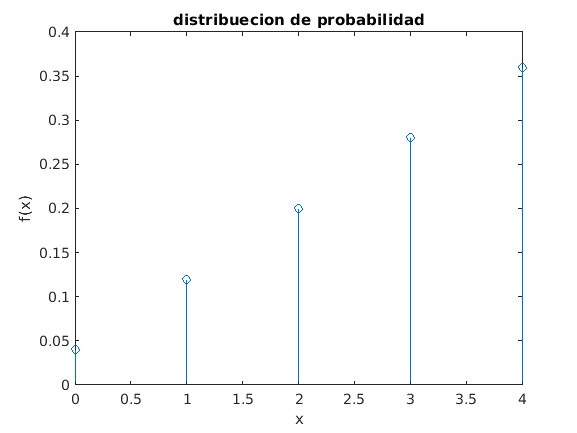

%grafica de distribucion de probabilidad
stem(x,f);
title('distribuecion de probabilidad')
xlabel('x')
ylabel('f(x)')

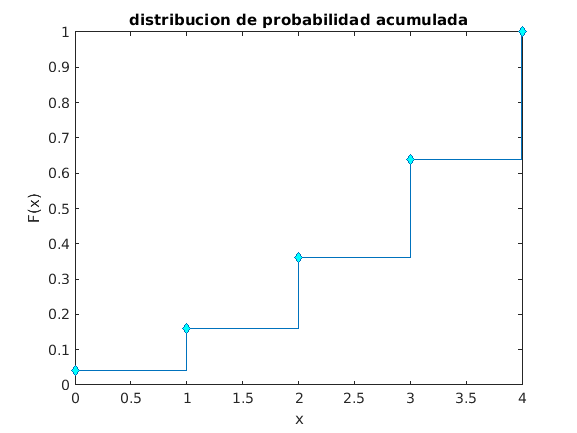

%grafica de distribucion de probabilidad acumulada
stairs(x,F,'LineWidth',1,'Marker','d','MarkerFaceColor','c')
title('distribucion de probabilidad acumulada')
xlabel('x')
ylabel('F(x)')

%encontrar la media
E=0;
for i=1:1:5
    E=E+x(i)*f(i);
end
E

E = 2.8000

%encontrar la varianza
V=0;
for i=1:1:5
    V=V+((x(i)-E)^2)*f(i);
end
V

V = 1.3600

%encontrar la media g(x)
Eg=0;
for i=1:1:5
    Eg=Eg+(((2*x(i)+1))*f(i));
end
Eg

Eg = 6.6000

%encontrar la varianza g(x)
Vg=0;
for i=1:1:5
    Vg=Vg+((2*x(i)+1-Eg)^2)*f(i);
end
Vg

Vg = 5.4400